# 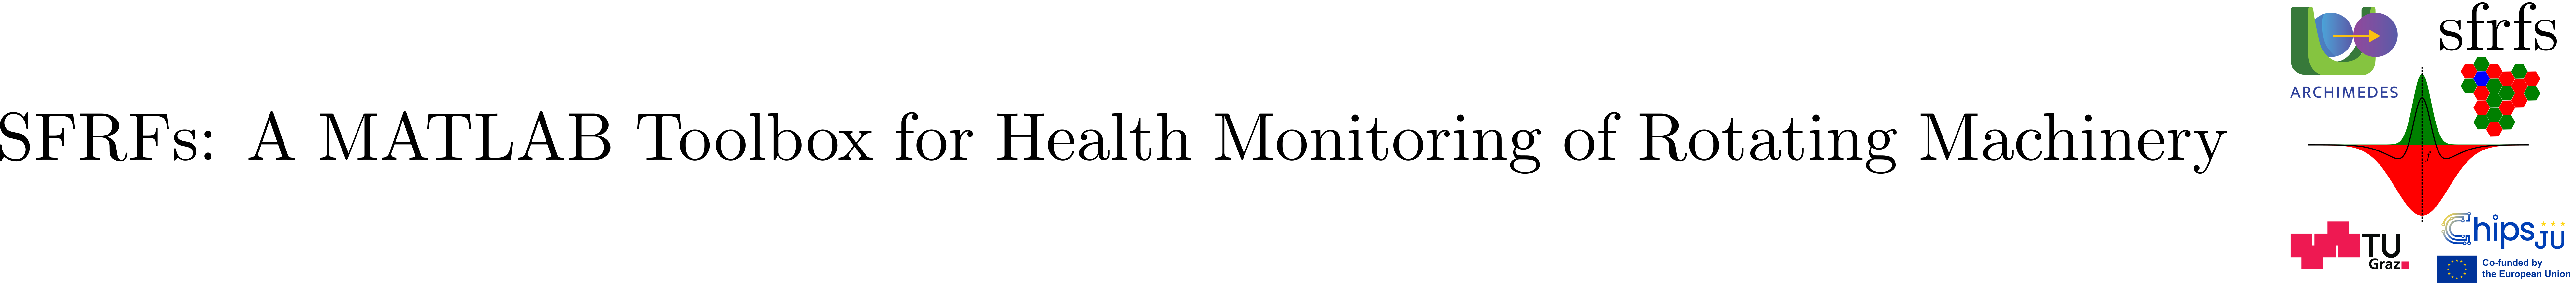

# OperatingConditions

## Summary

Class encapsulating a table of operating conditions with essential parameters for spectral fault analysis.

Key features:

- Stores operating conditions in a table with two columns: 'Speed' (Hz) and 'Load' (kN).

- Constructor validates that input speed and load vectors have matching dimensions.

- Provides a readable JSON-formatted string representation of the conditions table for logging and diagnostics.

- Raises dimension mismatch error if input vectors differ in length, enforcing data integrity.

- Designed as a foundational class to represent operating contexts for fault frequency band computations.

Typical usage involves creating an instance with vectors of speed and load values to represent discrete operating points influencing fault characteristics.

## Description

Operating conditions encapsulates possible (speed, load) pairs for rotating machinery. An internal table with columns **Speed** and **Load** stores the numeric values. Speed represents the rotor speed in Hz,  while Load specifies the system load in kN.

## Example

We illustrate the definition of operating conditions applicable to the [**XJTU-SY**](https://github.com/WangBiaoXJTU/xjtu-sy-bearing-datasets) rolling bearing run-to-failure dataset. The testbed comprises several groups of bearings, each operated at a fixed rotational speed and load, with vibration signals acquired using both horizontal and vertical acceleration sensors. Individual bearings are uniquely identified by a label. The mapping between bearing labels and operating conditions is shown in Table 1.

**Table 1**. Mapping of bearing labels to operating conditions in the  [**XJTU-SY**](https://github.com/WangBiaoXJTU/xjtu-sy-bearing-datasets) dataset.

### Object creation

Creating the operating conditions for Table 1 can be done as follows:

% define vector of rotor speeds
speeds = [35; 37.5; 40];
% define vector with system loads
loads  = [12; 11; 10];
% create the operating conditions
oc = OperatingConditions(speeds, loads)

oc =   OperatingConditions with properties:

    conditionsTable: [3×2 table]


### Access to internal table

The property conditionsTable gives access to the internal table:

% displaying internal table
disp(oc.conditionsTable);

    Speed    Load
    _____    ____

      35      12 
    37.5      11 
      40      10 



### `String representation`

The class is a value object and provides a (json) string rendering via toString method.

% string representation for the operating conditions table
disp(oc.toString());

[OperatingConditions: [{"Speed":35,"Load":12},{"Speed":37.5,"Load":11},{"Speed":40,"Load":10}]]


## API documentation

### MATLAB help

help OperatingConditions

  OPERATINGCONDITIONS Encapsulates a table of operating conditions.
 
    This class stores an operating conditions table having columns
    'Speed' and 'Load'.
 
    Example:
        speeds = [35; 37.5; 40];
        loads  = [12; 11; 10];
        oc = OperatingConditions(speeds, loads);
        disp(oc.conditionsTable)
 
    Properties:
        conditionsTable     - Table of [N x 2] with 'Speed' and 'Load'.
 
    Methods:
        OperatingConditions - Constructor (see below)
 
    Inputs:
        speed - Numeric column vector of speeds (Hz)
        load  - Numeric column vector of loads (kN)
 
    Raises:
        'sfrfs:OperatingConditions:DimAgree' if speed and load are not 
        the same length.
 
    Reference:
       B. Wang et al., “A Hybrid Prognostics Approach for Estimating 
       Remaining Useful Life of Rolling Element Bearings”, 
       IEEE Trans. Reliability, 2018.
       DOI: 10.1109/TR.2018.2882682

    Documentation for OperatingConditions
       doc OperatingCondi

### MATLAB documentation

doc OperatingConditions

Opens the full class documentation in the MATLAB Help Browser, including formatted examples, links to related functions, and extended descriptions.

## Source code

Operating conditions specifications are implemented in the class [OperatingConditions](matlab:open('../../OperatingConditions.m')).

## Test

Unit testing for the class is implemented in [TestOperatingConditions](matlab:open('../../../tests/TestOperatingConditions.m')).

% execute tests
res = runtests('Spectral Fault Receptive Fields/tests/TestOperatingConditions');

Running TestOperatingConditions
....
Done TestOperatingConditions
__________



% display summary of tests
SFRFsTestUtil.printTestSummary(res,80);

Test Name                                                                        | Result
-----------------------------------------------------------------------------------------
TestOperatingConditions/testValidInputs                                          | Passed
TestOperatingConditions/testSingleRow                                            | Passed
TestOperatingConditions/testMismatchedLengths                                    | Passed
TestOperatingConditions/testEmptyInputs                                          | Passed



## How to cite this work

Muñoz Gutiérrez, Stan, & Wotawa, Franz (2025). SFRFs: A MATLAB Toolbox for Health Monitoring of Rotating Machinery. Zenodo. DOI: [10.5281/zenodo.17631784](http://10.0.20.161/zenodo.17631784).

## References

- Biao Wang, Yaguo Lei, Naipeng Li, Ningbo Li, “A Hybrid Prognostics Approach for Estimating Remaining Useful Life of Rolling Element Bearings”, IEEE Transactions on Reliability, pp. 1-12, 2018. [DOI: 10.1109/TR.2018.2882682](https://doi.org/10.1109/TR.2018.2882682).